clear;clc


## 通过传递函数搭建系统

num = 1;
den = [0.0014 2.1];
G = tf(num,den);

## 定义PID控制器

Kp = 50;  % 比例增益
Ki = 60000;   % 积分增益
Kd = -0.0006;   % 微分增益
PID_control = pid(Kp, Ki, Kd);   % PID 控制器


## 形成闭环系统

sys_open = PID_control * G;
sys_closed = feedback(sys_open,1);


## 仿真阶跃响应

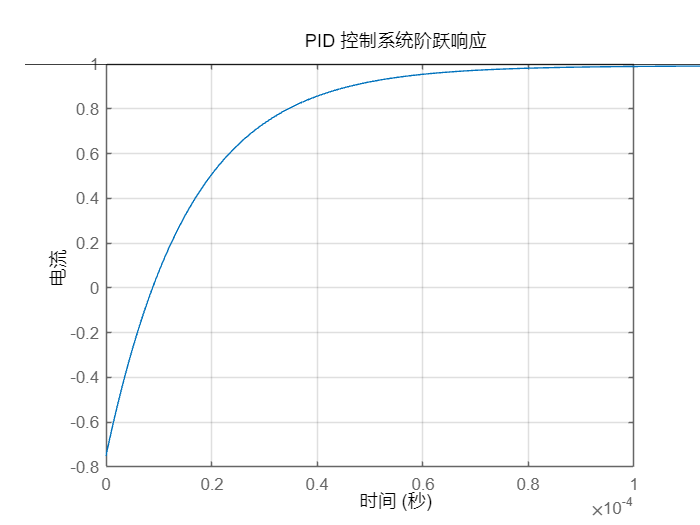

figure;
step(sys_closed);  % 绘制阶跃响应
title('PID 控制系统阶跃响应');
xlabel('时间');
ylabel('电流');
grid on;